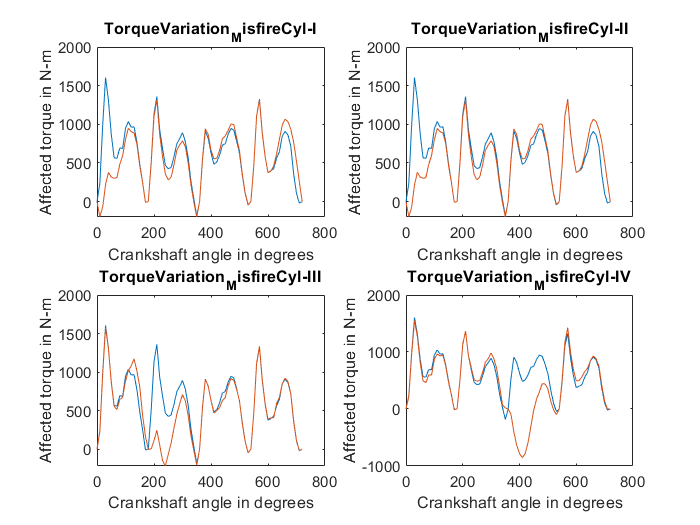

mass_piston=1.125;
La=0.0744;
n=3.47;
mass_cr=1.75;
mass_crank=1;
stroke=0.14;
Wavg=1800;                
coeff_speedchange=0.01;  
J_system = 7;
Wavg=(2*pi/60)*Wavg;
r=(stroke)/2;
L=n*r;
Lb=L-La;
Ma=(Lb/L)*mass_cr;
Mb=mass_cr-Ma;
M_rec=mass_piston+Mb;
Ph1 = fopen('healthycyl1.txt');       % handles for the files
Ph2 = fopen('healthycyl2.txt');
Ph3 = fopen('healthycyl3.txt');
Ph4 = fopen('healthycyl4.txt');
Pd1 = fopen('damagedcyl1.txt');
Pd2 = fopen('damagedcyl2.txt');
Pd3 = fopen('damagedcyl3.txt');
Pd4 = fopen('damagedcyl4.txt');
formatspec = '%f';
Fg = zeros([73 8]);
Fg(:,1) = fscanf(Ph1,formatspec);
Fg(:,2) = fscanf(Ph2,formatspec);
Fg(:,3) = fscanf(Ph3,formatspec);
Fg(:,4) = fscanf(Ph4,formatspec);
Fg(:,5) = fscanf(Pd1,formatspec);
Fg(:,6) = fscanf(Pd2,formatspec);
Fg(:,7) = fscanf(Pd3,formatspec);
Fg(:,8) = fscanf(Pd4,formatspec);
theta = 0:pi/18:4*pi;
tcyl = zeros(8,73); %Torques of individual cylinders in both conditions in a matrix. 
% 8 columns for 8 kinds of cylinders. 
%(Healthy and misfirng case for each cylinder)
for c=1:8
    if c==2|c==3|c==6|c==7
        z = theta + pi;
    else 
        z = theta;
    end
    x = ((r*cos(z)+L-(r^2*(sin(z)).^2))/(2*L));
    tanphi = (tan(asin((sin(z))/n)));
    Fi = (M_rec*r*(Wavg^2))*(cos(z)+(cos(2*z))/n);
    for c1=1:73
        tcyl(c,c1) = x(c1)*tanphi(c1)*(Fg(c1,c)-Fi(c1));    
    end
end
T = zeros(5,73);
T(5,:) = tcyl(1,:)+tcyl(2,:)+tcyl(3,:)+tcyl(4,:); %healthy torque
T(1,:) = tcyl(5,:)+tcyl(2,:)+tcyl(3,:)+tcyl(4,:); %misfire in 1st
T(2,:) = tcyl(6,:)+tcyl(1,:)+tcyl(3,:)+tcyl(4,:); %misfire in 2nd
T(3,:) = tcyl(7,:)+tcyl(2,:)+tcyl(1,:)+tcyl(4,:); %misfire in 3rd
T(4,:) = tcyl(8,:)+tcyl(2,:)+tcyl(3,:)+tcyl(1,:); %misfire in 4th
theta = (180/pi)*theta;
subplot(2,2,1)
plot(theta,T(5,:),theta,T(1,:))
title('TorqueVariation_MisfireCyl-I')
xlabel('Crankshaft angle in degrees');
ylabel('Affected torque in N-m');
subplot(2,2,2)
plot(theta,T(5,:),theta,T(1,:));
title('TorqueVariation_MisfireCyl-II')
xlabel('Crankshaft angle in degrees');
ylabel('Affected torque in N-m');
subplot(2,2,3)
plot(theta,T(5,:),theta,T(3,:))
title('TorqueVariation_MisfireCyl-III')
xlabel('Crankshaft angle in degrees');
ylabel('Affected torque in N-m');
subplot(2,2,4)
plot(theta,T(5,:),theta,T(4,:))
title('TorqueVariation_MisfireCyl-IV')
xlabel('Crankshaft angle in degrees');
ylabel('Affected torque in N-m');

save('Torque.mat')








